- **Note - we work with double images 0-1 so values for k and sigma will be normalized by 255**

## **Q2 - Perona Malik**

Write the function implementing nonlinear Perona-Malik diffusion (use as input Parrot image). 

Use the diffusion coefficient c(s) = 1/(1 + (s/k)2), where s = |∇u|.

### 2.a - 1D Denoising

A step with noise. Add noise, std=0.1 (where the step is between [0,1]). 

Compare denoising with linear diffusion and with P-M. Choose appropriate threshold k for P-M.

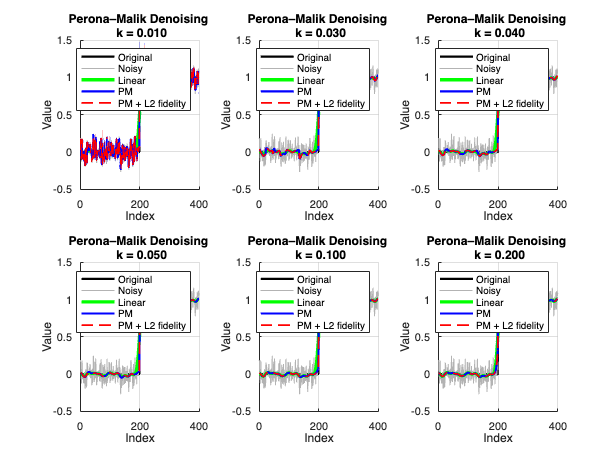


===== Gradient Magnitude Statistics =====
True signal |grad u0|:
  mean = 0.0025, std = 0.0501, max = 1.0000

Noise only |grad noise|:
  mean = 0.1155, std = 0.0798, max = 0.4845

Noisy signal |grad u_noisy|:
  mean = 0.1180, std = 0.0947, max = 1.1319

Noisy signal noise:
  mean = -0.0007, std = 0.0981, max = 0.2843


clear; close all; clc;
Q2()

**Answer:**

We want our signal U to be as close as it can be to a step function, the range between $0\ldotp 05\le K_{\textrm{pm}} \le 0\ldotp 1$ gives us the best result (depending on the seed), if we use $K_{\textrm{pm}} \ge 0\ldotp 2$then we get closer to Linear Diffusion which we do not want to do.

We remember that $K_{\textrm{pm}}$ thresholds the gradients $|\nabla u|$, even though the noise std $\sigma_{n\;} =0\ldotp 1$the effective gradient noise can be smaller which will allow to $K_{\textrm{pm}} <|\nabla u|$as we can see in our example, $\sigma_{n\;} =0\ldotp 1$ but $\textrm{std}\left(|\nabla u|\right)\approx 0\ldotp 05$which means we should choose $K_{\textrm{pm}} \approx 0\ldotp 06$.

### 2.b.i - 2D Denoising

Add noise of std=10,std=20.Denoise with several k values.

How does k relate to the noise std?

dt=0.200000

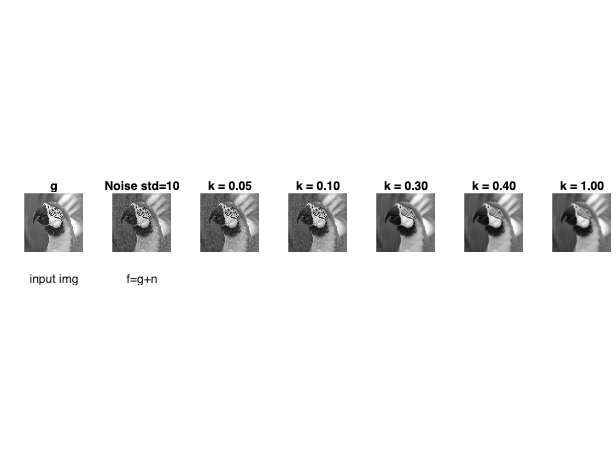

%% 2D Perona–Malik experiments using student's diffusionPM()
clear; close all; clc;
k = [0.05,0.1,0.3,0.4,1]; dt = 0.2; lambda = 0.1; T = 5;psnr=0;

%KPM(noise_level,k,dt,T,lamda)
KPM(10,k,dt,T,lambda,psnr)

dt=0.200000

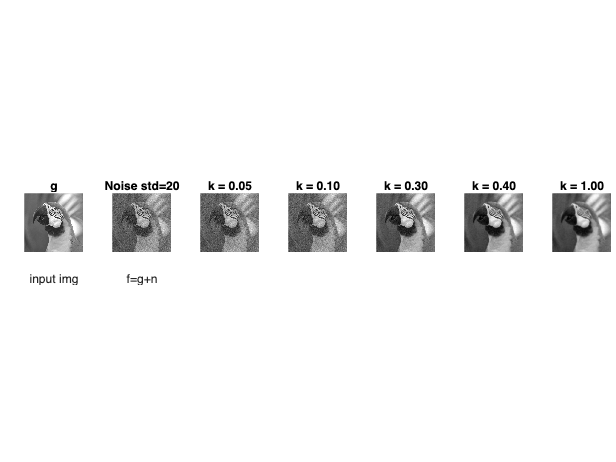

KPM(20,k,dt,T,lambda,psnr)

**Answer:**

As explained earlier, when we use PM coeff, then theortically if $K_{\textrm{pm}} <|\nabla u|$ then we get Inverse diffusion, and if $|\nabla u|<K_{\textrm{pm}}$then we have non-linear diffusion.

K related to the noise std by increasing the gradient of $|\nabla u|$, so K needs to scale proportionally with the noise level.

We see this phenomenon:

 @$\sigma_{n\;} =10$ The threshold $K_{\textrm{pm}} <0\ldotp 3$ Inverse Diffusion, $K_{\textrm{pm}} \ge 0\ldotp 3$ Diffusion

  @$\sigma_{n\;} =10$ The threshold $K_{\textrm{pm}} <0\ldotp 4$ Inverse Diffusion, $K_{\textrm{pm}} \ge 0\ldotp 4$ Diffusion

### **2.b.ii - **

Perform the experiments with two different time steps: ∆t = 0.2 and ∆t = 1. Explain the results.

dt=0.200000

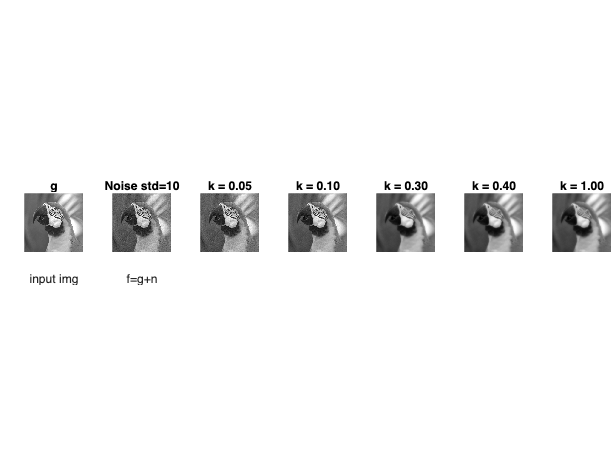

clear; close all; clc;
k = [0.05,0.1,0.3,0.4,1]; dt = 0.2; lambda = 0.1; T = 15;psnr=0;
%KPM(noise_level,k,dt,T,lamda)
KPM(10,k,dt,T,lambda,psnr)

dt=1.000000

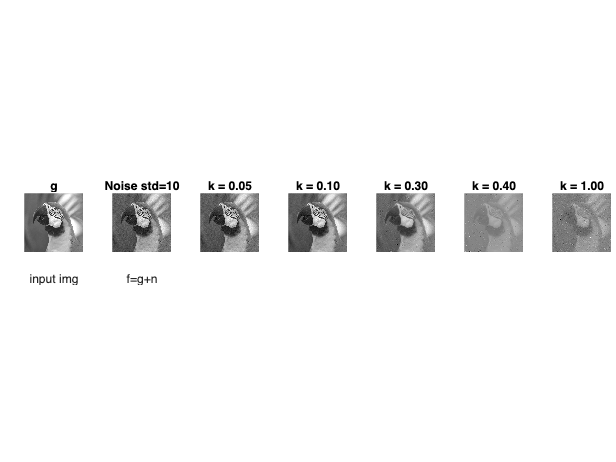


k = [0.05,0.1,0.3,0.4,1]; dt = 1; lambda = 0.1; T = 15;psnr=0;
KPM(10,k,dt,T,lambda,psnr)

**Answer:**

We know we have the CFL condition  $\Delta t\le \frac{h^p }{M\cdot \max \left(c\left(x\right)\right)}$ in PM we have  $\Delta t\le 0\ldotp 25$

When $\Delta t>0\ldotp 25$ is large, we will get fast evolutions with possible instability like oscillations and artifact and numerical errors and overshooting the steady state (מתבדר). 

When $\Delta t>>0\ldotp 25$ is too large (does not comply with CFL) then the image will get destroyed, and also the Min\Max thingy does not work, we can see the expected results in the photos.

when$\Delta t=0\ldotp 2<0\ldotp 25$ we get a stable evolution, and gradual denoising where the edges are preserved well.

The Perona–Malik parameter  k must scale with the noise level, since it thresholds gradient magnitudes rather than intensity noise. Smaller time steps ensure numerical stability and controlled diffusion. The SNR evolution exhibits a clear maximum, motivating the need for an automatic stopping rule. A practical and effective criterion is based on stabilization of inter-iteration changes, which correlates well with the optimal denoising time even without access to ground truth.

### 2.b.iii.

Take noise with std=10. Denoise with k = 10. Compute the SNR curve, SNR(t) as a function of the evolution time t, what do you see?

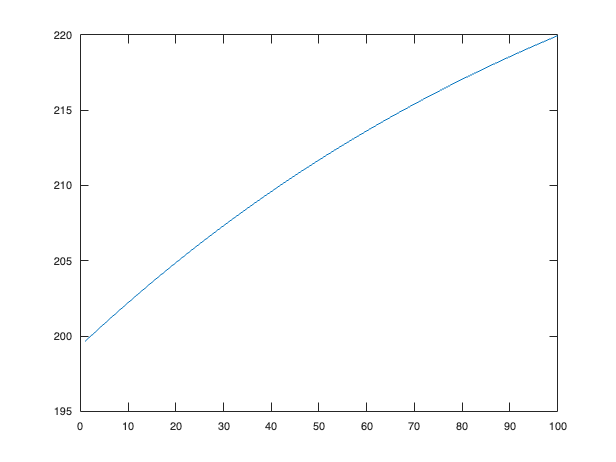

clear; close all; clc;
kpm = 10; dt = 0.1; lamda = 0.1; T =10;psnr=1;
%KPM(noise_level,k,dt,T,lamda)
%KPM(10,k,dt,T,lambda,psnr)


g = (imread('Ex1/parrot.png'));
g = double(im2gray(g));
noise_std = 10;
f = g + noise_std*randn(size(g));
u = f; iter = round(T/dt);
[u,mean_vals,std_vals,SNR] = diffusionPM(f,u,g,iter,dt,lamda,kpm);
figure;plot(SNR)

figure; imshow(u);

**Answer:**

We expect the SNR to go up because the noise is removed, and then once the noise is removed we will converge into a solution that can freeze, and we get a piece-wise constant regions at steady state, and the diffusion no longer will help because it will not affect the edges, and only the textures\high frequencies. 

Contrary to linear diffusion, no significant over-smoothing is observed even after many iterations. Perona–Malik diffusion admits nontrivial steady states due to its edge-stopping mechanism. Once noise is removed, diffusion is strongly suppressed both in flat regions and across edges, causing the evolution to effectively stop. As a result, the image does not converge to a constant and over-smoothing is avoided.a

### 2.b.iv.

Creative part (10 points). Suggest a method / criterion to stop automatically the evolution at a good time-point (SNR- wise or according to another quality measure). Important: SNR or MSE is not available for an actual algorithm (since ground truth is not available). Check your idea.

NEED TO FIXXXX

% --- Load and preprocess image ---
I = im2double(imread('Ex1/parrot.png'));
I = im2gray(I);

% --- Parameters ---
noise_levels = 10;    % e.g., [10, 20]
kpm = 0.4;              % e.g., [0.01,0.05,0.1,0.5,1]
dt           = 0.2;
lambda       = 0.1;            % fidelity weight
T            = 5;              % total time
iter         = round(T/dt);    % max iterations
sigma = 0.2;
% Automatic stopping parameters
autoStop = true;
epsilon  = 0.01;
patience = 3;
f = I + sigma * randn(size(I)); % noisy image

[u, mean_vals, std_vals, SNR, stop_iter] = diffusionPM2(f,f,I,iter,dt,lambda,kpm,autoStop,epsilon,patience);
        
fprintf('Stopped automatically at iteration %d\n', stop_iter);

Stopped automatically at iteration 25


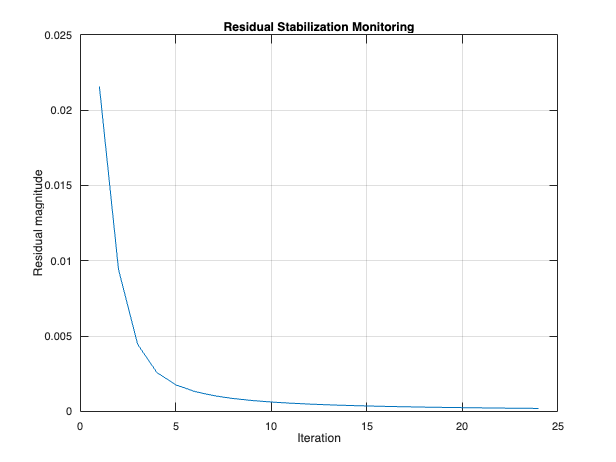

residuals = sqrt(diff(mean_vals).^2 + diff(std_vals).^2); % simple proxy
figure; plot(residuals);
xlabel('Iteration'); ylabel('Residual magnitude');
title('Residual Stabilization Monitoring');
grid on;

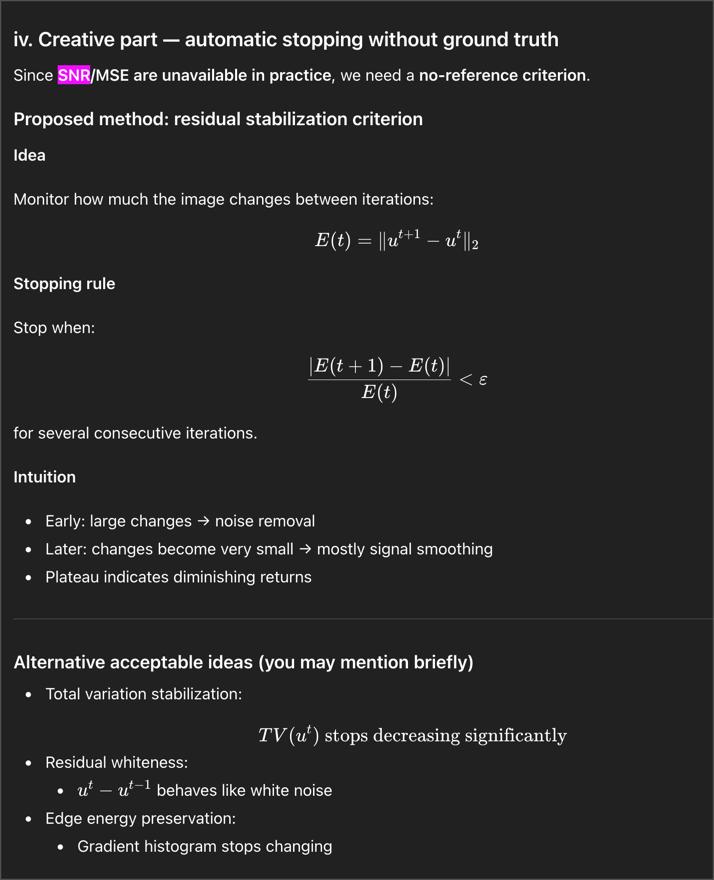


function [u,mean_vals,std_vals,SNR] = diffusionPM(f,u,g,iter,dt,lamda,kpm)
mean_vals = zeros(1,iter);
std_vals = zeros(1,iter);
SNR = zeros(1,iter);

for i=1:iter
[ux,uy] = grad(u);
ax = ux./(1+((abs(ux)/kpm)^2));
ay = uy./(1+((abs(uy)/kpm)^2));
u_t = div(ax,ay);
fidelity_t = f-u;
u = u+dt.*(u_t+lamda*fidelity_t);
mean_vals(i)=mean(u(:));
std_vals(i)=std(u(:));
%SNR(i) = 20*log10( norm(g(:)) / norm(g(:)-u(:)) );
SNR(i)= sum(g(:).^2)/(sum((g(:)-u(:)).^2));
end

end



%in images we assume h=1
function [fx,fy] = grad(V)
%forward difference gradient
fx = V(:,[2:end,end])-V;%select all rows, and shift cols +1 right, and duplicate last col again so we get direlhe boundry of 0
fy = V([2:end,end],:)-V;
end

function bd = div(Vx,Vy)
%backward difference divergence
fx = Vx - Vx(:,[1,1:end-1]); fx(:,1)=Vx(:,1); fx(:,end)=-Vx(:,end-1);
fy = Vy - Vy([1,1:end-1],:); fy(1,:)=Vy(1,:); fy(end,:)=-Vy(end-1,:);
bd = fx + fy;
end



function KPM(noise_level,k,dt,T,lambda,psnr)

I = im2double(imread('Ex1/parrot.png'));
I = im2gray(I);

noise_levels = noise_level;
k_values = k;%[0.01,0.05,0.1,0.5,1];
%dt = 0.2;
%lambda = 0.1;   % no fidelity term in (b)

%T = 5;

fprintf("dt=%f",dt)
iter = round(T/dt);
figure;
tiledlayout(1,length(k)+2+psnr,"TileSpacing","tight","Padding","tight");
nexttile; imshow(I); title("g");xlabel("input img")

for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = I + sigma * randn(size(I));
   nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma*255));xlabel("f=g+n")

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        if psnr>0
                [u,~,~,SNR] = diffusionPM(f,f,I,iter,dt,lambda,kpm);
        else
                [u,~,~,~] = diffusionPM(f,f,f,iter,dt,lambda,kpm);
        end
       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(u,[]); title(sprintf('k = %.02f',kpm));
        if psnr>0
            nexttile;plot(SNR);xlabel('Time t');ylabel('SNR(t) Cruve');title(sprintf('k = %.2fd',k_values*255));grid on;
        end
        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end


end




function Q2()


N = 400;
u0 = zeros(1,N);
u0(N/2:end) = 1;


noise_std = 0.1;
noise = noise_std*randn(size(u0));
u_noisy = u0 + noise;


dt = 0.1;
num_iter = 200;


lambda = 0.001;

%k values to try
k_values = [0.01,0.03,0.04,0.05,0.1,0.2];

u_linear = u_noisy;

%fprintf("Noise Gradient=%f",diff(u_noisy(:)))

for it = 1:num_iter
    ux = [diff(u_linear), 0];
    ux_prev = [0, diff(u_linear)];
    lap = ux - ux_prev;        % discrete 2nd derivative
    u_linear = u_linear + dt * lap;
end


figure;
tiledlayout(2,3);
for idx = 1:length(k_values)

    k = k_values(idx);
    u_PM = u_noisy;       % PM only
    u_PM_fid = u_noisy;   % PM + L2

    %Run diffusion
    for it = 1:num_iter
        
        % ----- PM only -----
        ux_fwd  = [diff(u_PM), 0];
        ux_back = [0, diff(u_PM)];
        c_fwd  = 1 ./ (1 + (abs(ux_fwd)/k).^2);
        c_back = 1 ./ (1 + (abs(ux_back)/k).^2);
        div_PM = c_fwd .* ux_fwd - c_back .* ux_back;
        u_PM = u_PM + dt * div_PM;

        % ----- PM + Fidelity -----
        ux_fwd  = [diff(u_PM_fid), 0];
        ux_back = [0, diff(u_PM_fid)];
        c_fwd  = 1 ./ (1 + (abs(ux_fwd)/k).^2);
        c_back = 1 ./ (1 + (abs(ux_back)/k).^2);
        div_PM_fid = c_fwd .* ux_fwd - c_back .* ux_back;
        fidelity = -lambda * (u_PM_fid - u_noisy);
        u_PM_fid = u_PM_fid + dt * (div_PM_fid + fidelity);

    end

    nexttile;
    hold on;
    plot(u0, 'k', 'LineWidth', 2);
    plot(u_noisy, 'Color', [0.7 0.7 0.7]);
    plot(u_linear,  'g', 'LineWidth', 3);
    plot(u_PM, 'b', 'LineWidth',2);
    plot(u_PM_fid, 'r', 'LineWidth', 1.5,LineStyle='--');
    title(sprintf('Perona–Malik Denoising \n k = %.3f', k));
    legend('Original', 'Noisy','Linear', 'PM', 'PM + L2 fidelity');
    xlabel('Index'); ylabel('Value');
    grid on;

end



% ----- Compute gradients -----
grad_u0     = diff(u0);                 % true signal gradient
noise_only  = u_noisy - u0;              % isolate noise
grad_noise  = diff(noise_only);          % noise gradient
grad_noisy  = diff(u_noisy);             % total gradient

% ----- Absolute gradients -----
abs_grad_u0    = abs(grad_u0);
abs_grad_noise = abs(grad_noise);
abs_grad_noisy = abs(grad_noisy);

% ----- Print statistics -----
fprintf('\n===== Gradient Magnitude Statistics =====\n');

fprintf('True signal |grad u0|:\n');
fprintf('  mean = %.4f, std = %.4f, max = %.4f\n', mean(abs_grad_u0), std(abs_grad_u0), max(abs_grad_u0));

fprintf('\nNoise only |grad noise|:\n');
fprintf('  mean = %.4f, std = %.4f, max = %.4f\n',mean(abs_grad_noise), std(abs_grad_noise), max(abs_grad_noise));

fprintf('\nNoisy signal |grad u_noisy|:\n');
fprintf('  mean = %.4f, std = %.4f, max = %.4f\n', mean(abs_grad_noisy), std(abs_grad_noisy), max(abs_grad_noisy));
fprintf('\nNoisy signal noise:\n');
fprintf('  mean = %.4f, std = %.4f, max = %.4f\n', mean(noise), std(noise), max(noise));
end





function [u,mean_vals,std_vals,SNR,stop_iter] = diffusionPM2(f,u,g,iter,dt,lamda,kpm,autoStop,epsilon,patience)
% diffusionPM - Perona–Malik diffusion with optional automatic stopping
% Inputs:
%   f       : noisy input
%   u       : initial image (usually f)
%   g       : ground truth (for SNR calculation, optional)
%   iter    : max iterations
%   dt      : time step
%   lamda   : fidelity term weight
%   kpm     : PM contrast parameter
%   autoStop: true/false for residual stabilization stopping
%   epsilon : relative change threshold
%   patience: consecutive iterations for stopping
% Outputs:
%   u       : final denoised image
%   mean_vals,std_vals,SNR: evolution over iterations
%   stop_iter: iteration where auto-stopped (if used)

mean_vals = zeros(1,iter);
std_vals  = zeros(1,iter);
SNR       = zeros(1,iter);
stable_count = 0;
stop_iter = iter;

%if nargin<9, autoStop = false; end
%if nargin<10, epsilon = 1e-3; end
%if nargin<11, patience = 5; end


for i=1:iter
    [ux,uy] = grad(u);

    ax = ux ./ (1 + (abs(ux)/kpm).^2);
    ay = uy ./ (1 + (abs(uy)/kpm).^2);

    u_t = div(ax,ay);
    fidelity_t = f - u;

    u_new = u + dt.*(u_t + lamda*fidelity_t);

    % --- record stats ---
    mean_vals(i) = mean(u_new(:));
    std_vals(i)  = std(u_new(:));
    if nargin>=4 && ~isempty(g)
        SNR(i) = 20*log10( norm(g(:)) / norm(g(:)-u_new(:)) );
    else
        SNR(i) = NaN;
    end

    % --- residual stabilization ---
    if autoStop
        if i>1
            E = norm(u_new - u,'fro');
            E_prev = norm(u - u_old,'fro');
            rel_change = abs(E - E_prev)/E_prev;

            if rel_change < epsilon
                stable_count = stable_count + 1;
            else
                stable_count = 0;
            end

            if stable_count >= patience
                stop_iter = i;
                fprintf('Auto-stopped at iteration %d\n',i);
                mean_vals = mean_vals(1:i);
                std_vals  = std_vals(1:i);
                SNR       = SNR(1:i);
                u = u_new;
                return
            end
        end
    end

    u_old = u;
    u = u_new;
end
end
